recordFile = "./data/49/H60-L01_to_AUM-AL20.wav";
% recordFile = "./data/49/AUM-AL20_to_H60-L01.wav";
recordFile2 = "./data/49/AUM-AL20_to_H60-L01.wav";
samplingRate = 44100;
fBegin = 2000;
fEnd = 6000;
chirpTimeMs = 100;
device1D = 0.01;
device2D = 0.01;
soundSpeed = 340;

## 原始信号

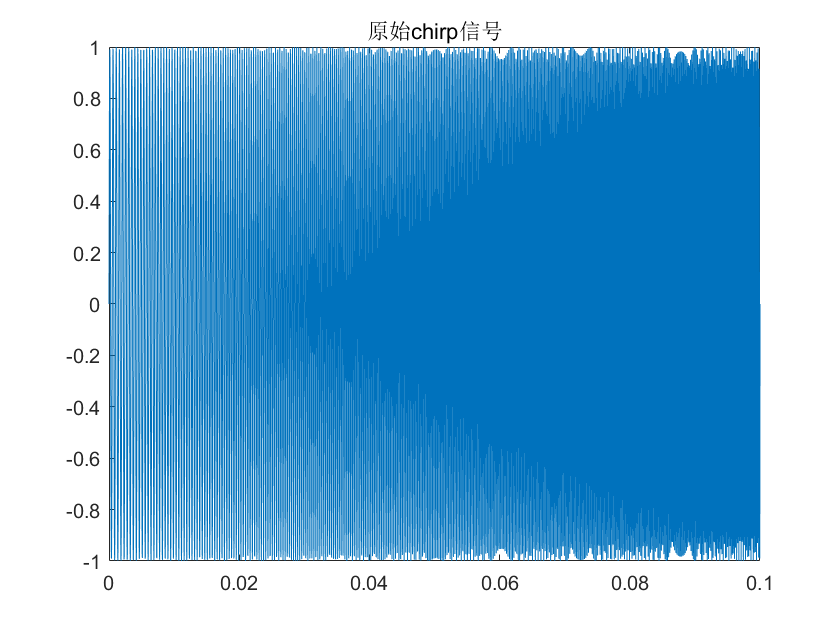

[originChirpT, originChirpY] = generateChirp(samplingRate,fBegin, fEnd, chirpTimeMs, 0);
%% 时域处理
plot(originChirpT, originChirpY);
title("原始chirp信号")

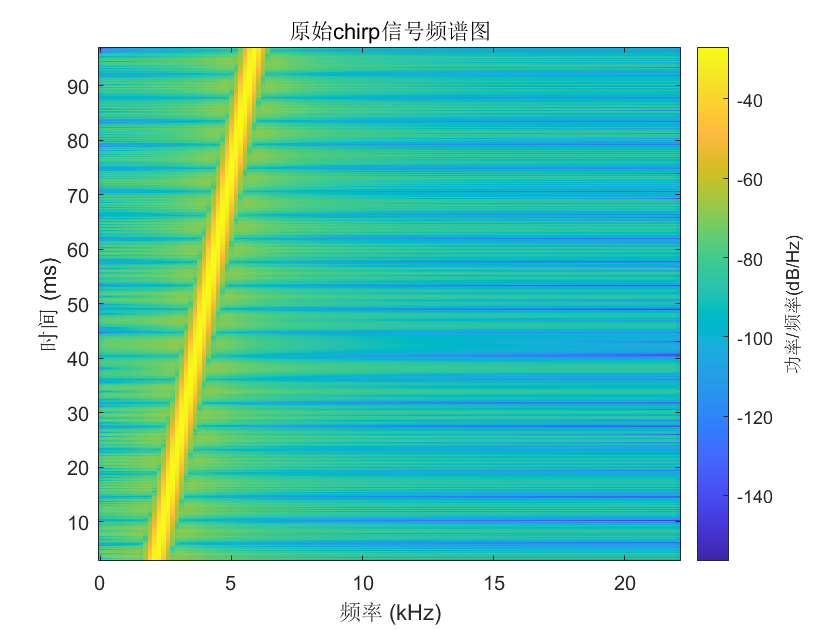

spectrogram(originChirpY, 256, 250, 256, samplingRate);
title("原始chirp信号频谱图")

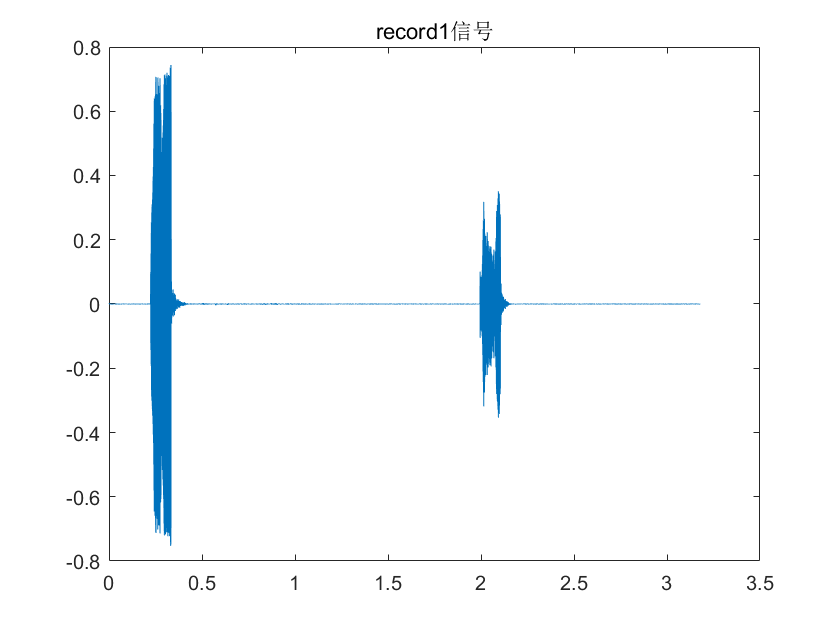



[recordY, recordFs] = audioread(recordFile);
len1 = length(recordY);
%% 时域处理
t1 = (0:len1-1)/recordFs;
plot(t1, recordY);
title("record1信号");

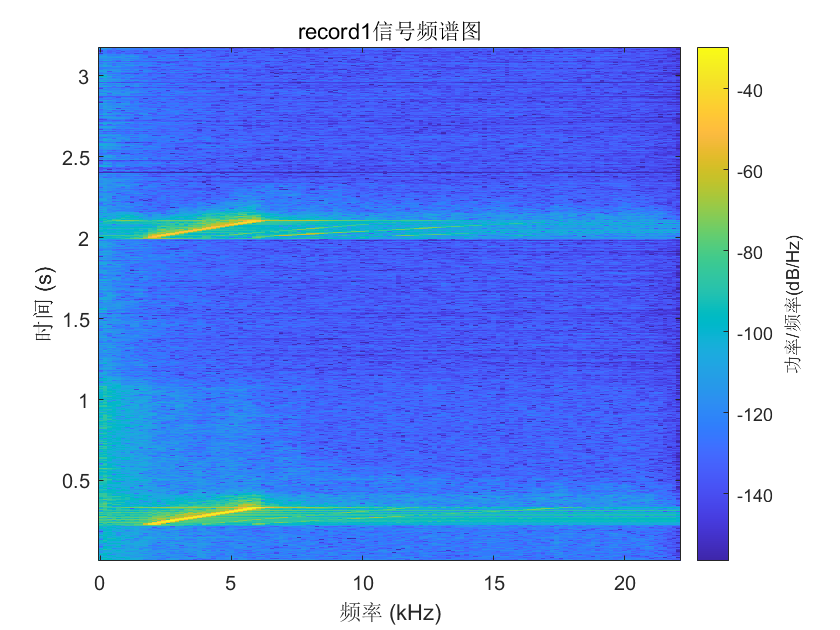

spectrogram(recordY, 256, 250, 256, samplingRate);
title("record1信号频谱图");

## 互相关

[c,lags] = xcorr(recordY, originChirpY)

c = 	1.0e+03 *

  -0.000000000000000
  -0.000000000000000
  -0.000000000000000
  -0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000
  -0.000000000000000


lags =      -140237     -140236     -140235     -140234     -140233     -140232     -140231     -140230     -140229     -140228     -140227     -140226     -140225     -140224     -140223     -140222     -140221     -140220     -140219     -140218     -140217     -140216     -140215     -140214     -140213     -140212     -140211     -140210     -140209     -140208     -140207     -140206     -140205     -140204     -140203     -140202     -140201     -140200     -140199     -140198     -140197     -140196     -140195     -140194     -140193     -140192     -140191     -140190     -140189     -140188


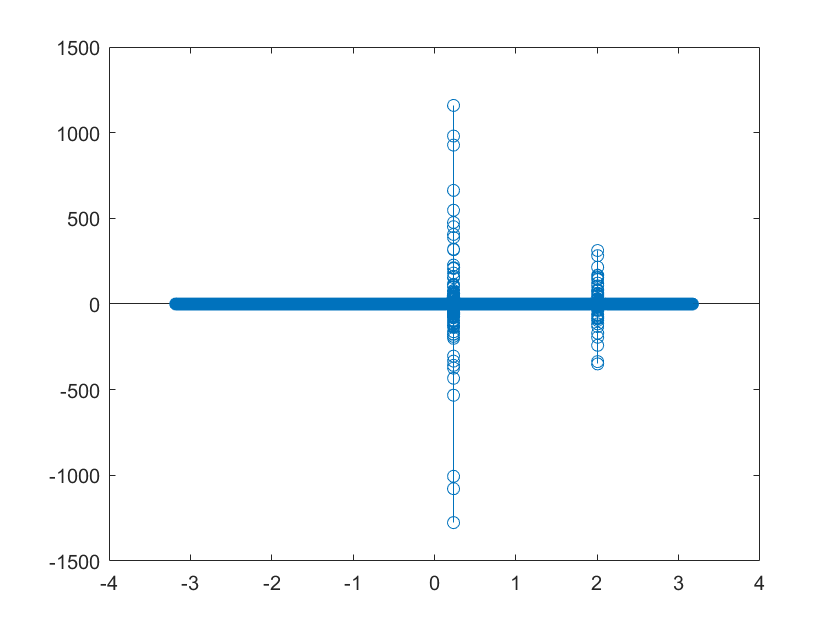

stem(lags / samplingRate, c)

% 原始信号数
stdSampleNum = length(originChirpY);

% 首先找到一个全局最大值
[maxValue, maxIndex] = max(c)

maxValue =      1.159141189266858e+03


maxIndex =       150556


rangeStart1 = maxIndex - stdSampleNum

rangeStart1 =       146145


rangeEnd1 = rangeStart1 + stdSampleNum + stdSampleNum - 1;
peak1 = lags(1, maxIndex)

peak1 =        10318


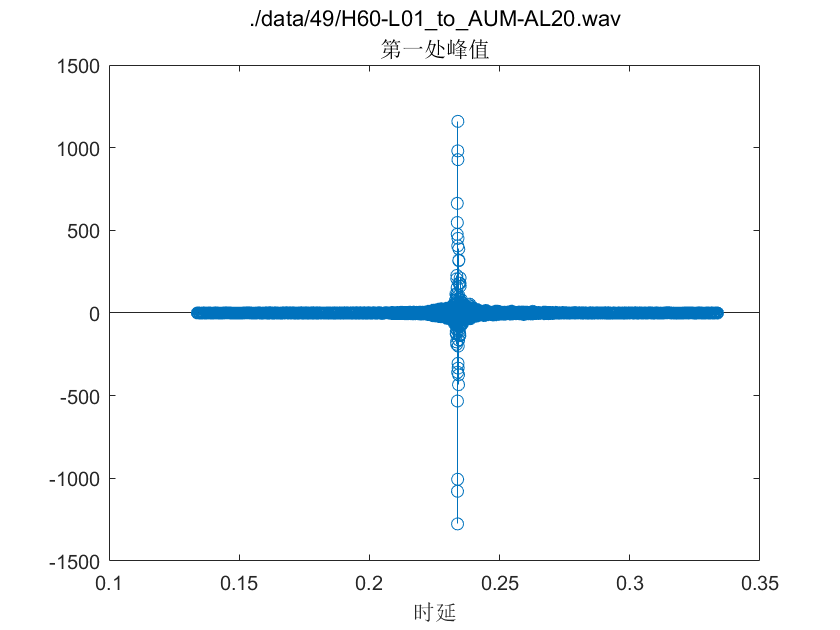

stem(lags(rangeStart1:rangeEnd1)/samplingRate, c(rangeStart1:rangeEnd1))
title({recordFile, "第一处峰值"}, 'Interpreter', 'none')
xlabel("时延")

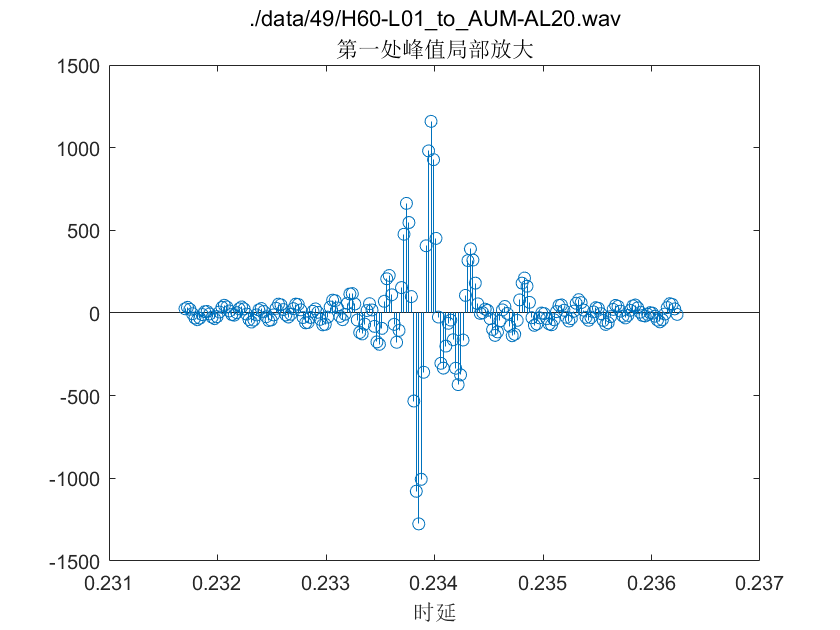

stem(lags(maxIndex-100:maxIndex+100)/samplingRate, c(maxIndex-100:maxIndex+100))
title({recordFile, "第一处峰值局部放大"}, 'Interpreter', 'none')
xlabel("时延")

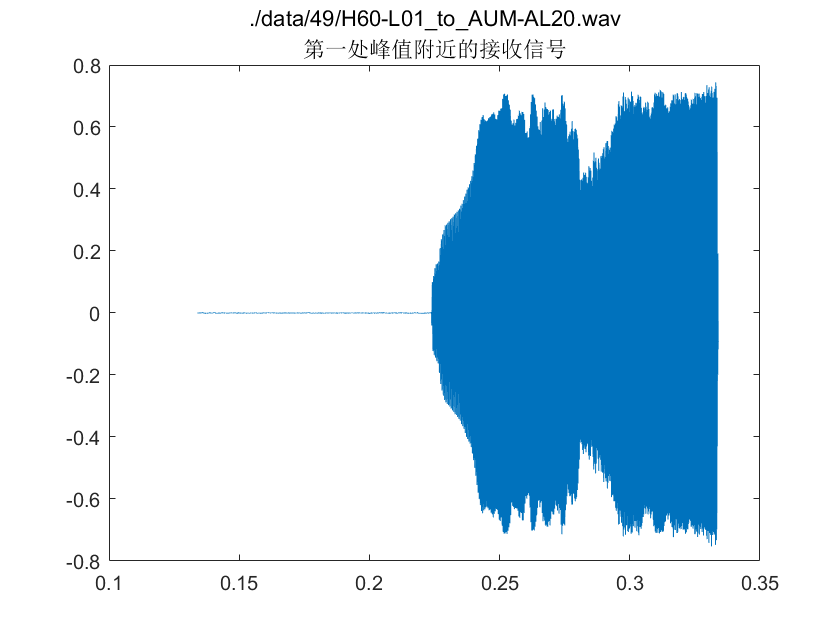



plot(t1(rangeStart1 - len1:rangeEnd1-len1), recordY(rangeStart1 - len1:rangeEnd1-len1));
title({recordFile, "第一处峰值附近的接收信号"}, 'Interpreter', 'none');

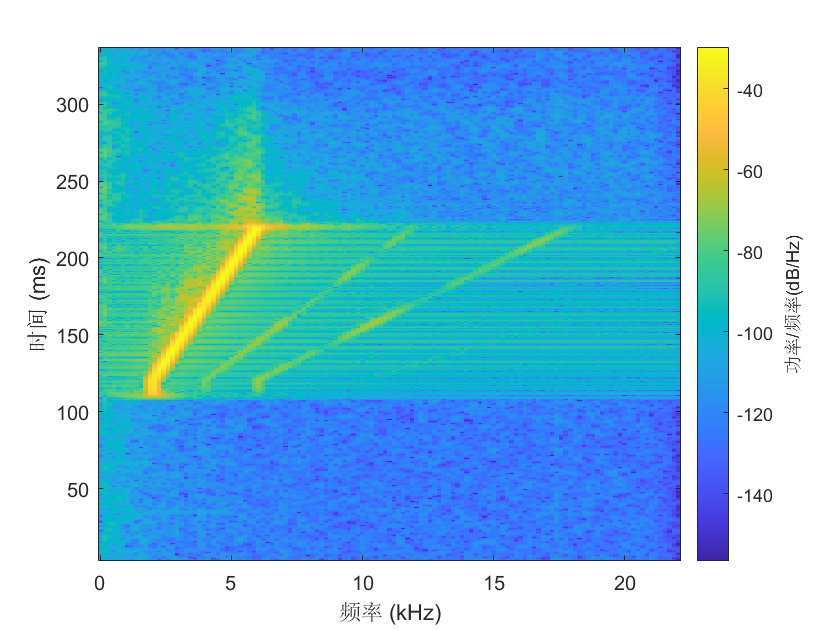

spectrogram(recordY(5000:20000), 256, 250, 256, samplingRate);


% 在其余两段中找另一个全局最大值
tmp = [c(1:rangeStart1 - 1); zeros(stdSampleNum + stdSampleNum, 1); c(rangeEnd1 + 1:length(c))]

tmp = 	1.0e+02 *

  -0.000000000000000
  -0.000000000000000
  -0.000000000000000
  -0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000
   0.000000000000000
  -0.000000000000000


[maxValue, maxIndex] = max(tmp)

maxValue =      3.123035282242921e+02


maxIndex =       228648


rangeStart2 = maxIndex - stdSampleNum

rangeStart2 =       224237


rangeEnd2 = rangeStart2 + stdSampleNum + stdSampleNum - 1;
peak2 = lags(1, maxIndex)

peak2 =        88410


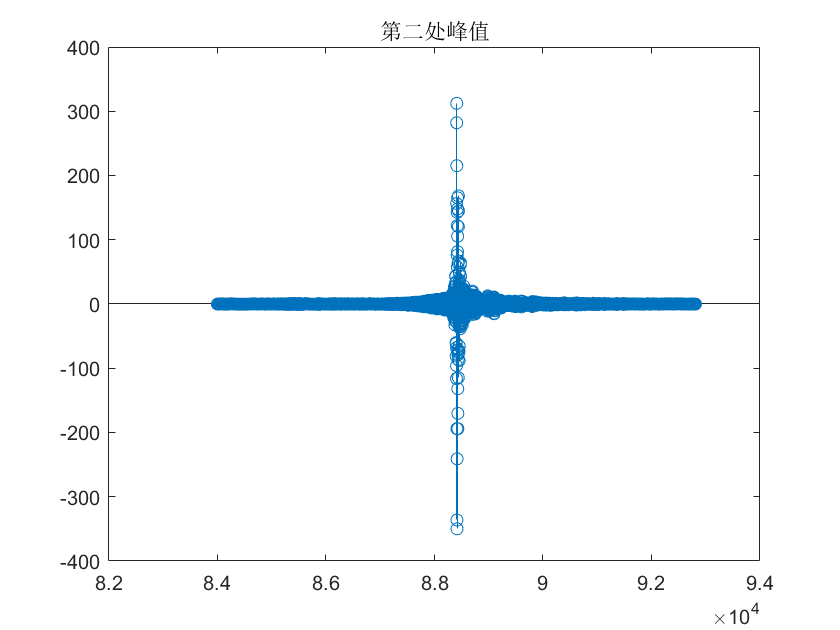

stem(lags(rangeStart2:rangeEnd2), tmp(rangeStart2:rangeEnd2))
title("第二处峰值")


format long
timeDifference = abs(peak1 - peak2) / samplingRate

timeDifference =    1.770793650793651



% computeTimeDifference(recordY, originChirpY, samplingRate)

## 计算距离

[path, name, ext] = fileparts(recordFile)

path = "./data/49"

name = "H60-L01_to_AUM-AL20"

ext = ".wav"

 path + "/" + name + "_"

ans = "./data/49/H60-L01_to_AUM-AL20_"

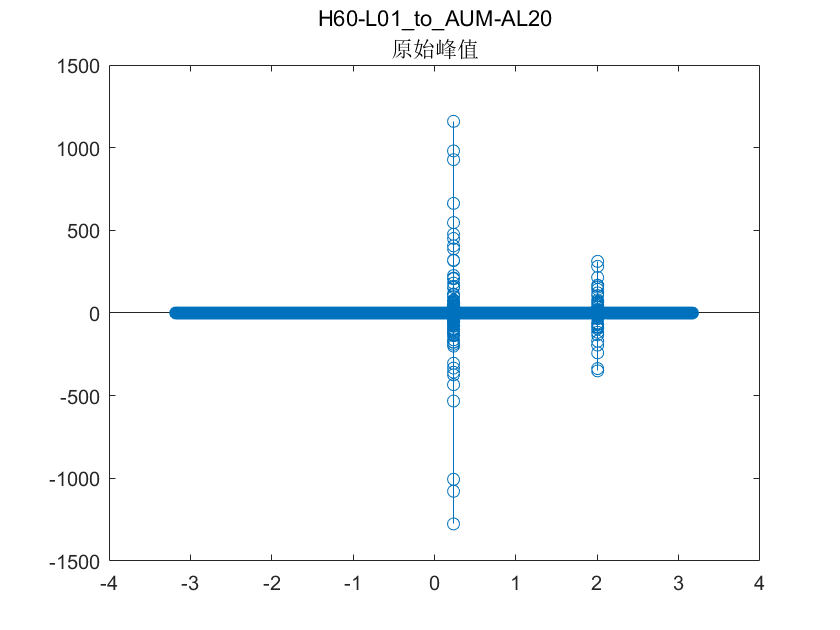

% [recordY, recordFs] = audioread(recordFile);
% td1 = computeTimeDifference(recordY, originChirpY, samplingRate)
% [recordY, recordFs] = audioread(recordFile2);
% td2 = computeTimeDifference(recordY, originChirpY, samplingRate)
% D = abs(td1 - td2) * soundSpeed / 2 + (device1D + device2D) / 2

computeDistance(recordFile, recordFile2, device1D, device2D, samplingRate, fBegin, fEnd, chirpTimeMs, soundSpeed)